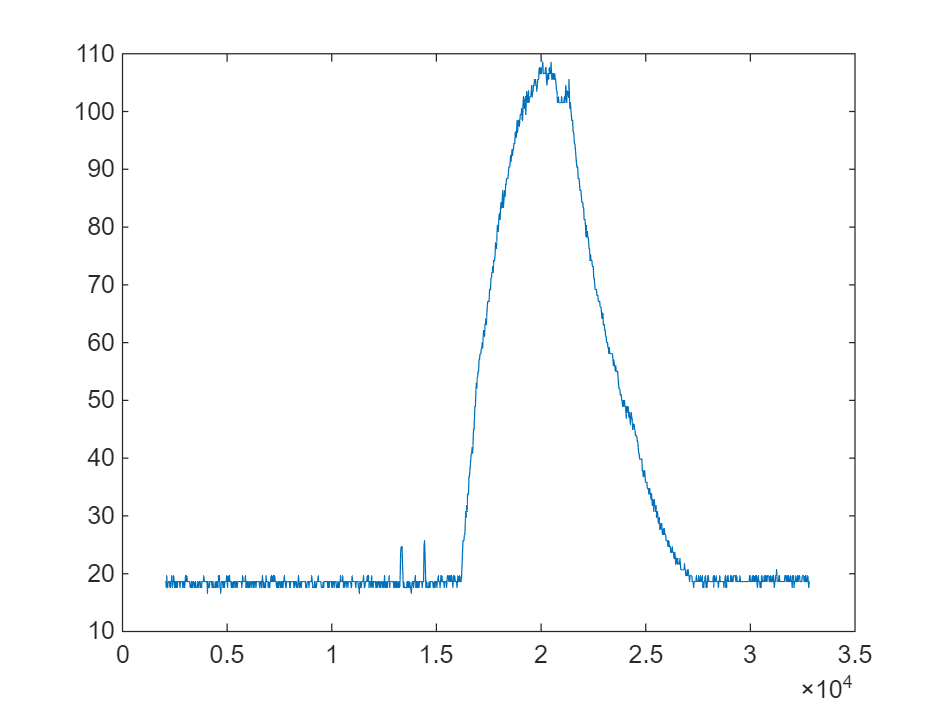

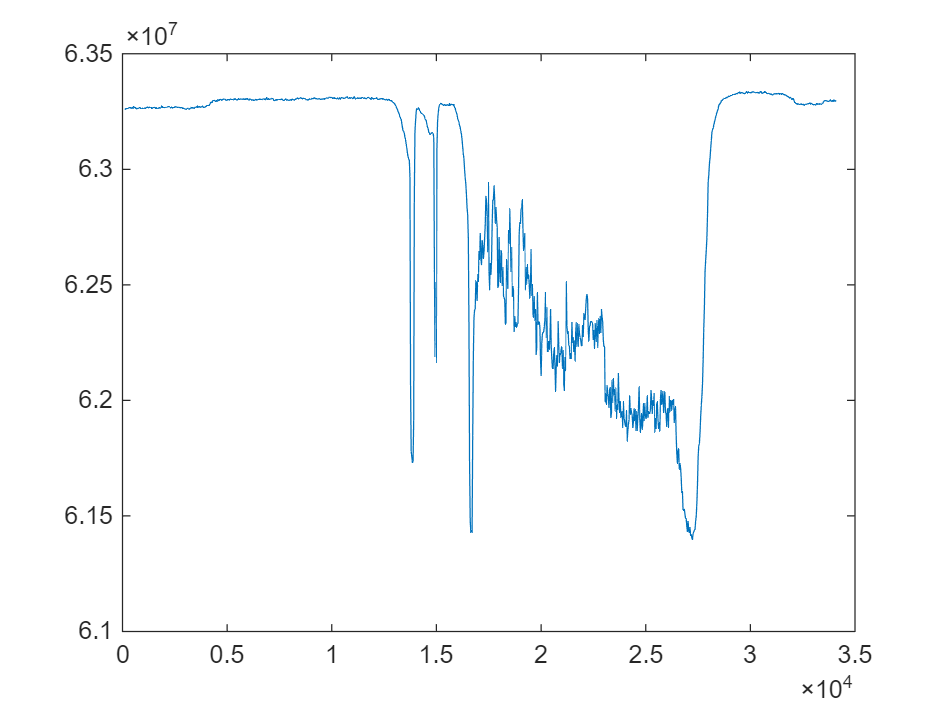

baseline_plate_mag = 18.3472

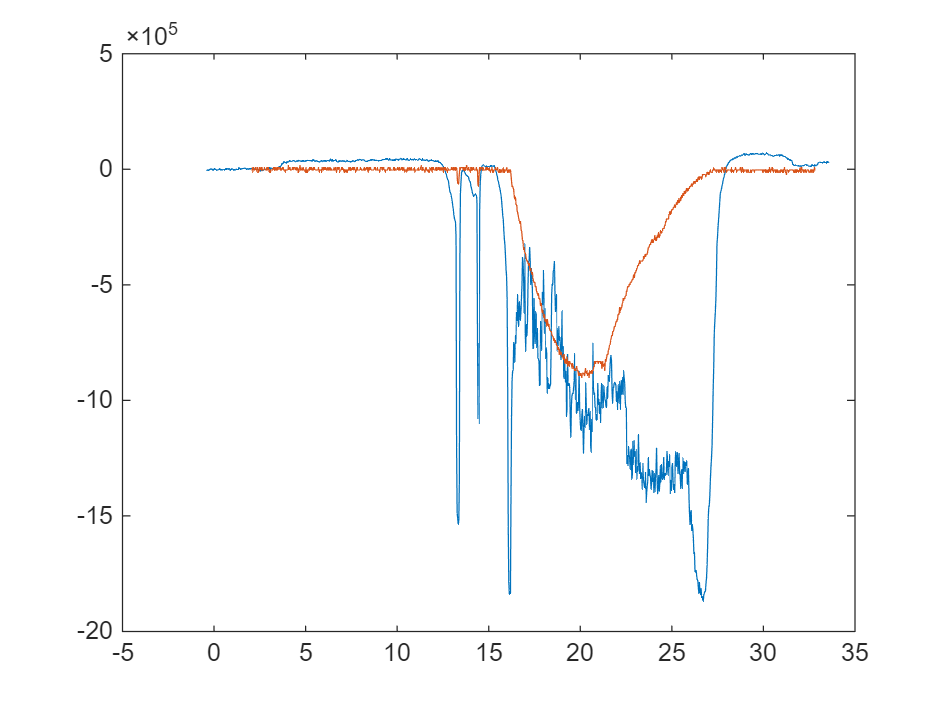

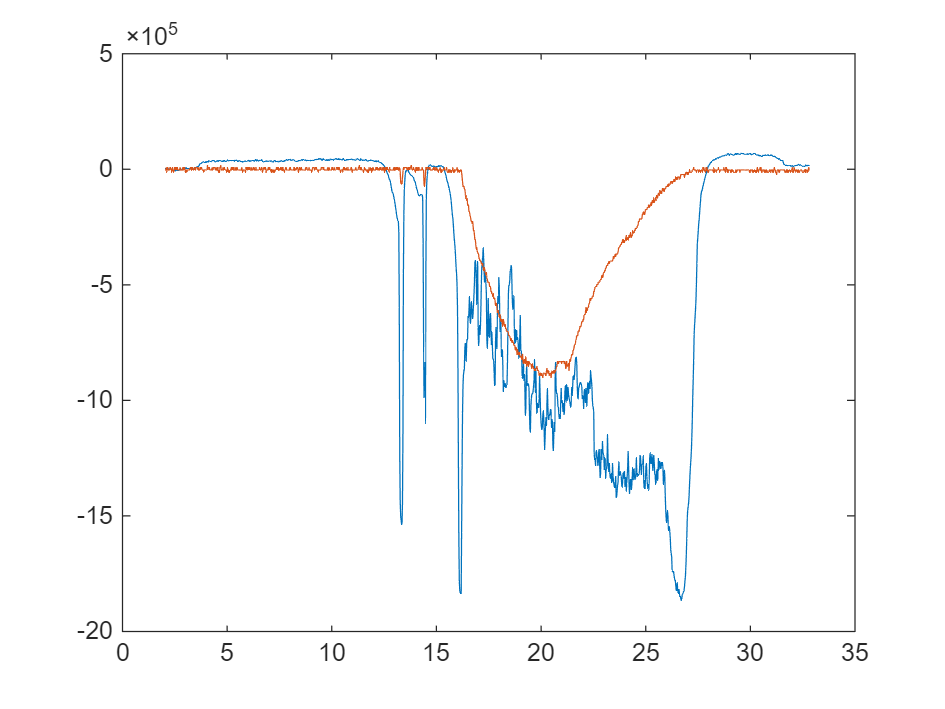

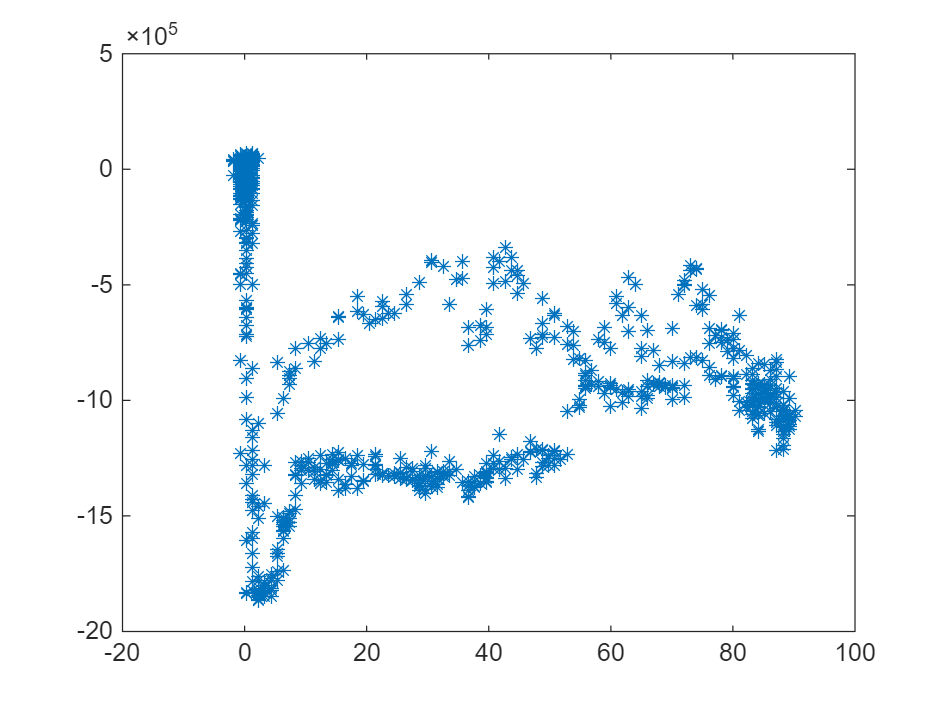

max_force = 2.3028

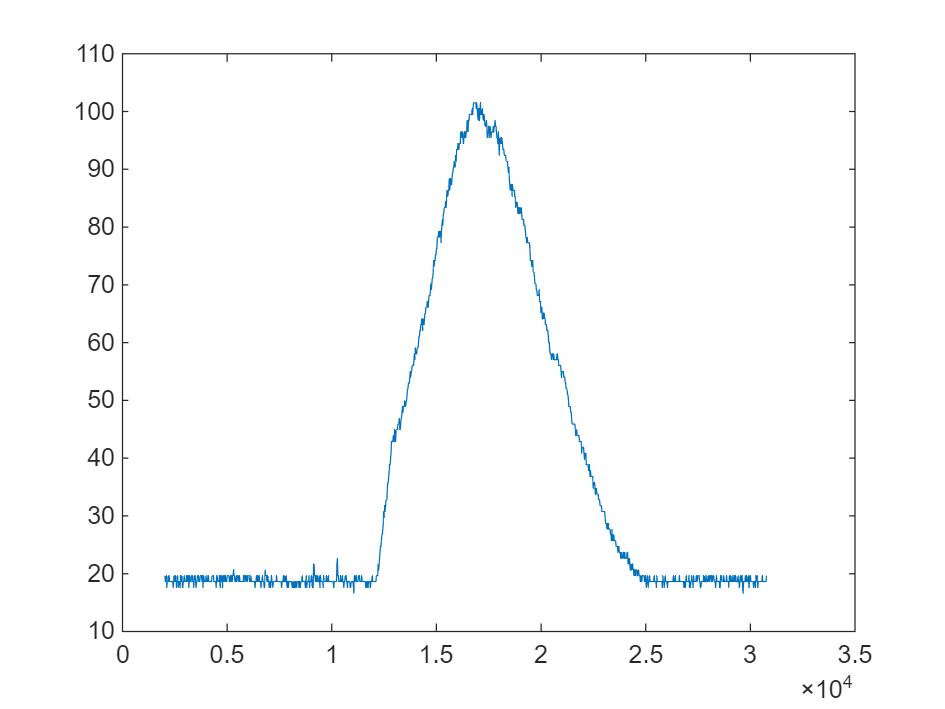

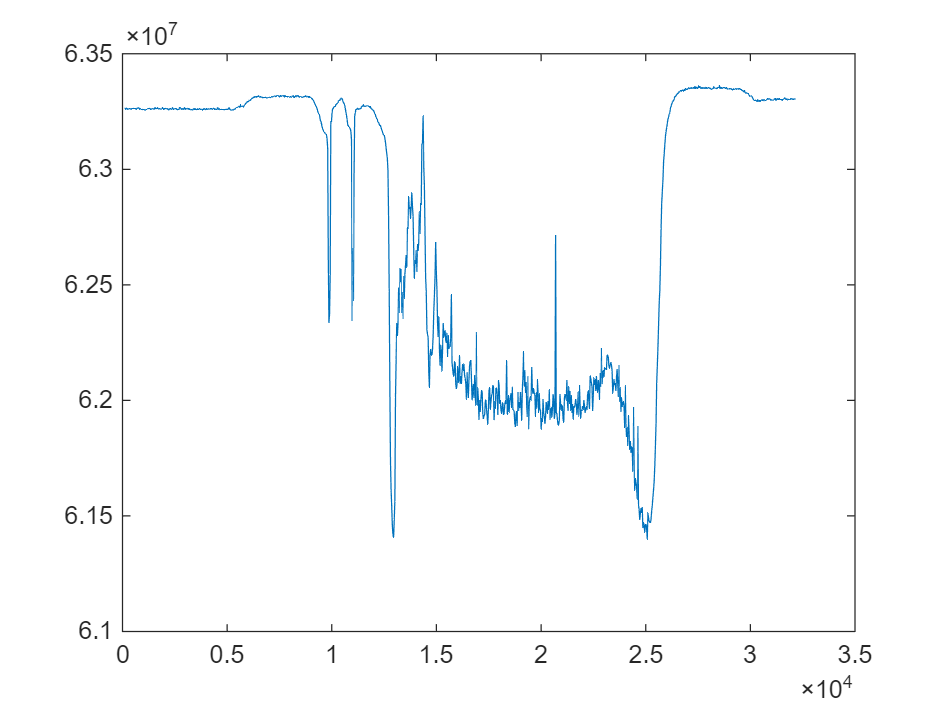

baseline_plate_mag = 18.8724

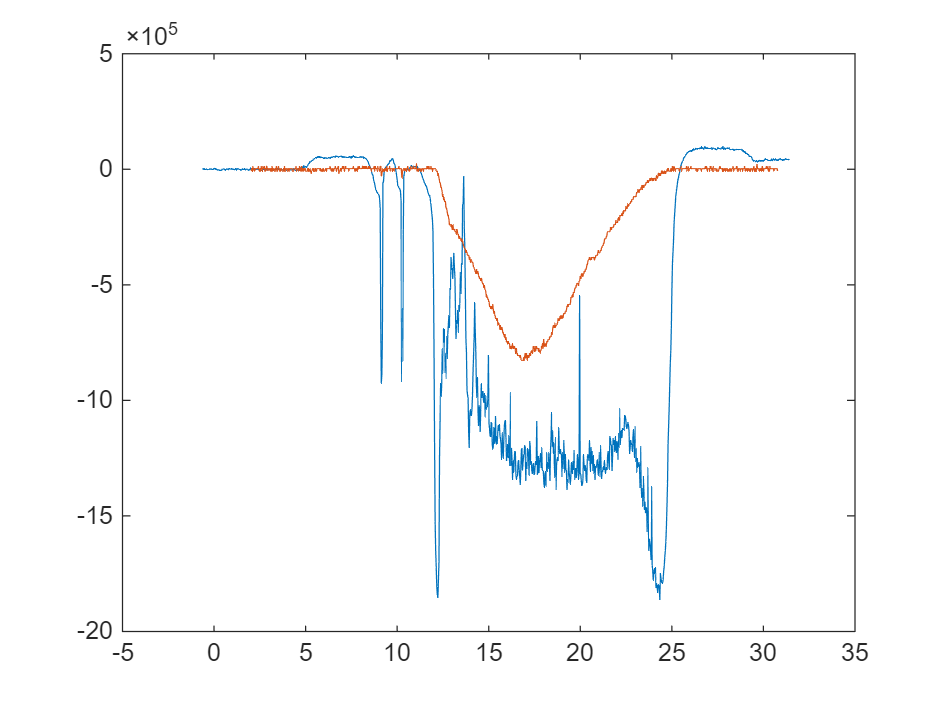

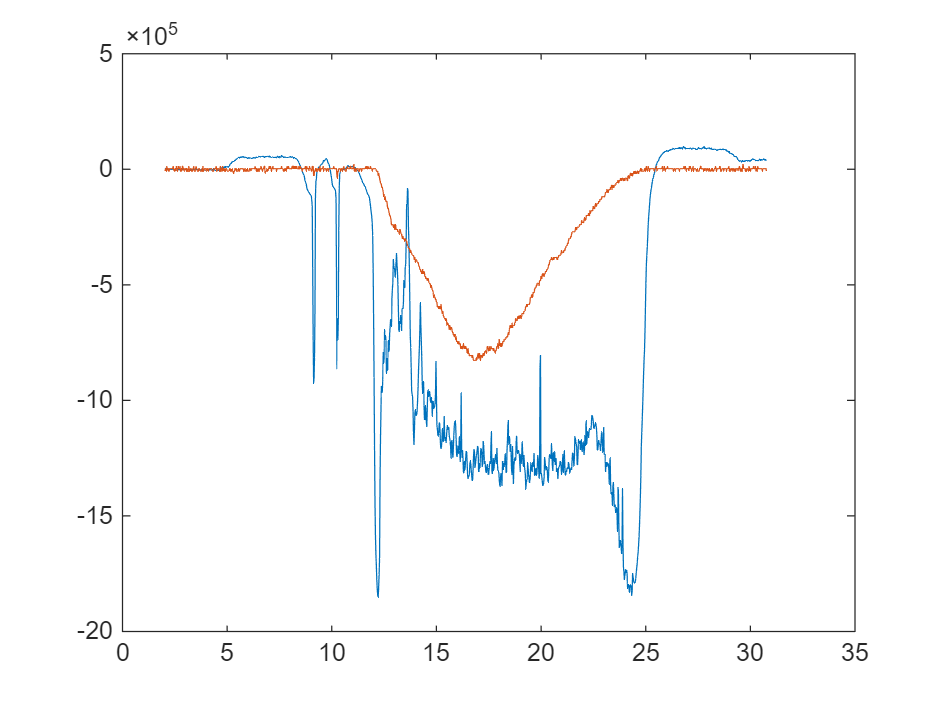

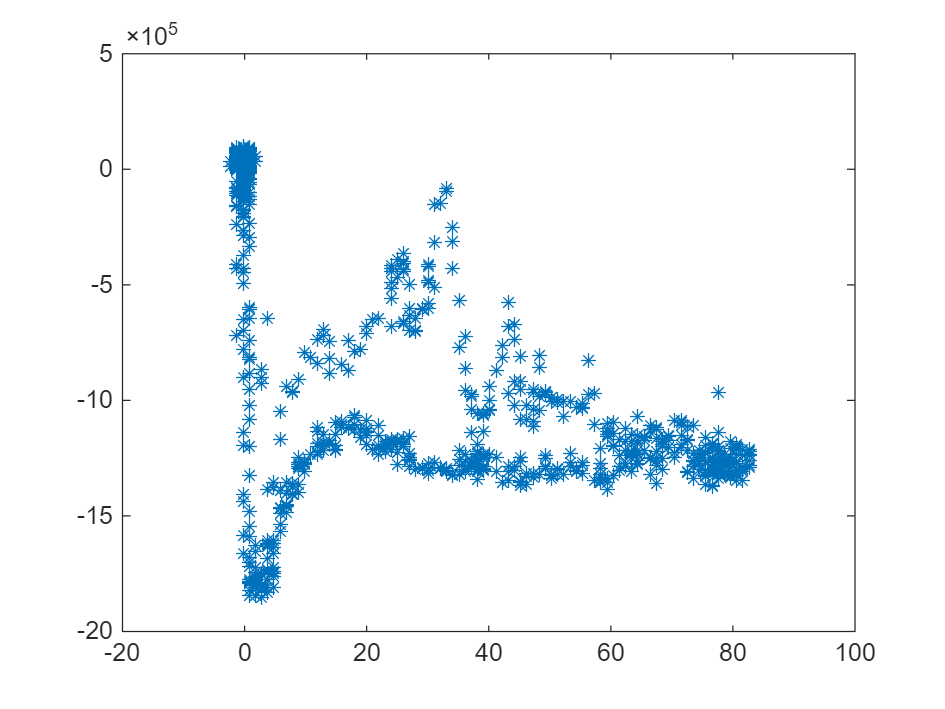

max_force = 2.7976

addpath("force_plate");
addpath("sensor");

data2plot = cell(1,2);
max_index = zeros(1,2);

for i = 1:2

    diff = [520, 732] ./1000;

    fp_name = strcat('fp_',num2str(i),'.txt');
    ss_name = strcat('ss_',num2str(i),'.txt');

    plate_data = readmatrix(fp_name,"Delimiter",",", 'Whitespace',' N');
    plate_data(end,:) = [];
    sensor_data = readmatrix(ss_name,"Delimiter",",");
    sensor_data(end,:) = [];

    figure;
    plot(plate_data(:,1),plate_data(:,2));
    figure;
    plot(sensor_data(:,1),sensor_data(:,2));

    % fp_1: 13334 = ss_1: 13854  ---- diff = 520
    % fp_2: 9132 = ss_2: 9864   ---- diff = 732


    baseline_plate_mag = mean(plate_data(1:100,2))

    plate_time = plate_data(:,1)./1000;
    plate_mag = plate_data(:,2) - baseline_plate_mag;
    sensor_time = sensor_data(:,1)./1000-diff(i);
    sensor_mag = sensor_data(:,2) - mean(sensor_data(1:100,2));

    adj_plate_mag = plate_mag * (-10000);

    figure;
    plot(sensor_time,sensor_mag);
    hold on
    plot(plate_time,adj_plate_mag);
    hold off

    sensor_mag_interp = interp1(sensor_time,sensor_mag,plate_time);

    figure;
    plot(plate_time,sensor_mag_interp);
    hold on
    plot(plate_time,adj_plate_mag);
    hold off

    abs_plate_mag = adj_plate_mag ./ (-10000);

    figure;
    plot(abs_plate_mag,sensor_mag_interp,'*')
    
    data2save = [abs_plate_mag,sensor_mag_interp];
    data2plot{i} = data2save;
    [min_sensor,min_ind] = min(sensor_mag_interp);
    max_force = abs_plate_mag(min_ind)
    max_index(i) = min_ind;

end

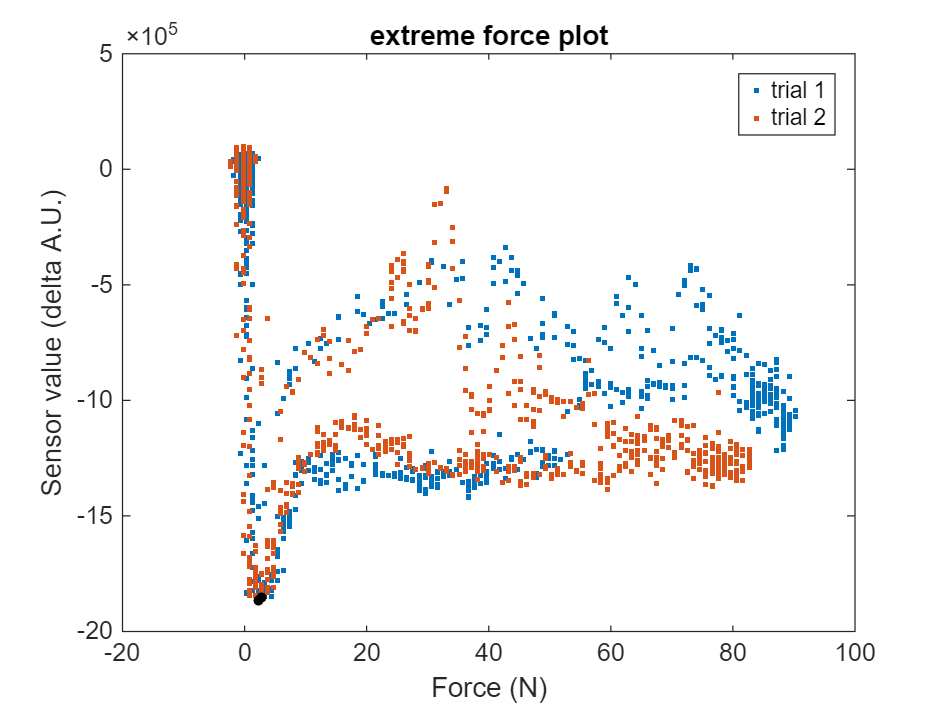


figure;
plot(data2plot{1}(:,1),data2plot{1}(:,2),'.')
hold on
plot(data2plot{2}(:,1),data2plot{2}(:,2),'.')
% plot(data2plot{3}(:,1),data2plot{3}(:,2),'.')
plot(data2plot{1}(max_index(1),1),data2plot{1}(max_index(1),2),'k.','MarkerSize',12)
plot(data2plot{2}(max_index(2),1),data2plot{2}(max_index(2),2),'k.','MarkerSize',12)
% plot(data2plot{3}(max_index(3),1),data2plot{3}(max_index(3),2),'k.','MarkerSize',12)
hold off
legend('trial 1','trial 2')
title('extreme force plot')
xlabel('Force (N)')
ylabel('Sensor value (delta A.U.)')